# Analyzing Neural Time Series Data

Matlab code for Chapter 4 script B Mike X Cohen

This code accompanies the book, titled "Analyzing Neural Time Series Data" (MIT Press). Using the code without following the book may lead to confusion, incorrect data analyses, and misinterpretations of results. Mike X Cohen assumes no responsibility for inappropriate or incorrect use of this code. 

## Basic plotting

% Matlab visual windows are called figures. Make a new figure with the command figure. 

figure % opens a new figures
plot(1:10,(1:10).^2); % plot X by Y ；X = 1~10，Y = X^2

% run this line after the previous one. note that it overwrites the
% previous plot
plot(1:10,log(1:10)) % X = 1~10，Y = logX

% now try this: 
plot(1:10,(1:10).^2,'linewidth',3);
hold on % this command enables overwriting
plot(1:10,log(1:10)*30,'r-d') % plot in red and with thicker lines. type "help plot" to learn more

% Drawing a line is simple, but can be a bit tricky at first. You need to
% define the start and end points in the X and Y (and also Z if you are
% plotting in 3D) axes:
plot([2 9],[60 60],'k')
plot([1 10],[0 100],'m:')

% now release the hold, and plot something else
hold off
plot(1:10,(1:10)*3)

% Of course, you can plot the information in variables:
x = 0:.1:1;
y = exp(x);
plot(x,y,'.-')

% x and y need to be of equal length, otherwise you'll get an error:
x = 0:.1:1;
y = [0 exp(x)];
plot(x,y,'.-')

% you can plot multiple lines simultaneously if they are in a matrix
clf % stands for clear-figure
plot(100:100:1000,rand(10,3))
% ranlize 0~10 3 times
% now let's add some extra features...
title('Random lines')
xlabel('x-axis label... maybe time? maybe space?')
ylabel('voltage (\muV)') % note that the "\mu" is converted to the greek lower-case character
legend({'line 1';'line 2';'line 3'}) % this is a cell array!

% close a figure:
close

% if you know the figure number, or have a handle to it (we'll get to this
% later), you can also open and close specific figures.
figure(10)
figure(100)
figure(103)

close([100 ...  An elipse at the end of a line allows you to write comments and continue the code on the next line. This is convenient for long lines of code that you want to be visible on a single screen without using the horizontal scrollbar. 
    103])

## plotting lines in 3D space

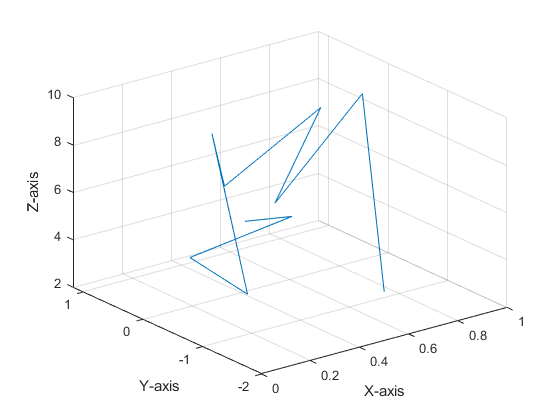

% If you feel constrained by two dimensions, fear not! Matlab also allows you to 
% plot data in three dimensions. This becomes useful in chapters 11-13 when
% introducing complex wavelets. 

% Plotting a line in a 3D space is easy. First, define data in 3 dimensions. 
n = 10;
dataX = rand(1,n);
dataY = randn(1,n);
dataZ = rand(1,n)*10;

% Now simply use plot3 the same way you would use plot, 
% but with three inputs:
figure
plot3(dataX,dataY,dataZ)

grid on % sometimes useful，畫上格線

rotate3d % this command will allow you to click-and-drag on the figure to spin the data around

% adding other features to the plot works the same as with a normal plot,
% e.g.,
xlabel('X-axis')
ylabel('Y-axis')
zlabel('Z-axis')



% You might instead have a 3D matrix, e.g.,
data3d = randn(3,30);
plot3(data3d)

Error using plot3
Not enough input arguments.

% Although the previous line seems like it should work, it unfortunately
% doesn't. You'll need to input each dimension separately:
plot3(data3d(1,:),data3d(2,:),data3d(3,:),'ko-','linew',3,'markerface','m') 
% you can use the same extra inputs to define line features as you would with the normal plot function
axis off
axis square % also try tight and normal

## slightly more advanced: get and set

"set" allows you to access specific properties of graphics. set uses "parameter-value pair" operations, which you will use often in plotting, as well as in some other advanced functions.

plot(1:10,rand(10,3))
set(gca,'xtick',1:2:9); % gca = "get current axis"; note the parameter-value pair afterwards
set(gca,'xtick',1:2:9,'xticklabel',{'one';'three';'five';'seven';'nine'}) 
% can put multiple parameter-value pairs in one function

% the complement to set is get. type "get(gca)" to see a list of parameters
% you can change
get(gca)

                       ALim: [0 1]
                   ALimMode: 'auto'
                 AlphaScale: 'linear'
                   Alphamap: [1×64 double]
          AmbientLightColor: [1 1 1]
               BeingDeleted: off
                        Box: on
                   BoxStyle: 'back'
                 BusyAction: 'queue'
              ButtonDownFcn: ''
                       CLim: [0 1]
                   CLimMode: 'auto'
             CameraPosition: [5.5000 0.5000 17.3205]
         CameraPositionMode: 'auto'
               CameraTarget: [5.5000 0.5000 0]
           CameraTargetMode: 'auto'
             CameraUpVector: [0 1 0]
         CameraUpVectorMode: 'auto'
            CameraViewAngle: 6.6086
        CameraViewAngleMode: 'auto'
                   Children: [3×1 Line]
                   Clipping: on
              ClippingStyle: '3dbox'
                      Color: [1 1 1]
                 ColorOrder: [7×3 double]
            ColorOrderIndex: 4
                 ColorScale: 'line

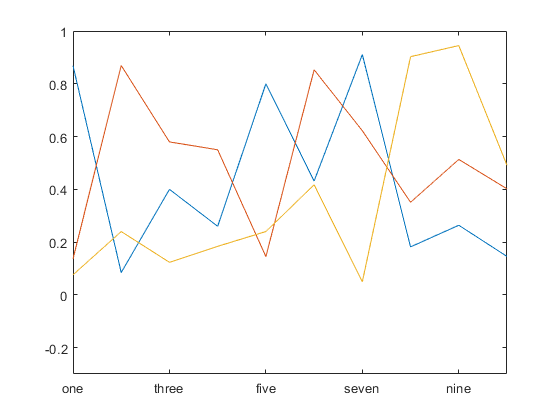

% you can also access (and return output from) axis properties:
axis_ylim = get(gca,'YLim'); % axis_ylim is the lower and upper bounds of the y-axis

% you can also assign axis properties using variables or functions:
the_ylim_i_want = [-.3 -cos(pi)];
set(gca,'YLim',the_ylim_i_want);


% If you have multiple axes or plotting objects, you can assign pointers (called handles) to
% the objects. It is good practice to include a lower-case 'h' in the name
% of the variable, to make it clear that these are handles:
figure
ploth = axes;
plot(ploth,1:10,randn(10,3));
title('Random lines')
set(ploth,'ydir','reverse') % this makes positive up, useful for ERP plotting
set(gca,'xlim',[5 10]); % you can also change the x-axis limits

% note that 'gca' points to the "current" axis, or the one most recently used. 
% You can mouse-click on an axis to make it current.

% you can also change properties of figures, e.g.: 
set(gcf,'Color',[.6 0 .8],'name','My purple figure!','numberTitle','off')

% Things can get slightly confusing, so make sure you use informative variable names.
title('Hello there')
titleh = get(gca,'Title'); % the "title" property is a handle to the title object
get(titleh)

        BackgroundColor: 'none'
           BeingDeleted: off
             BusyAction: 'queue'
          ButtonDownFcn: ''
               Children: [0×0 GraphicsPlaceholder]
               Clipping: off
                  Color: [0 0 0]
            ContextMenu: [0×0 GraphicsPlaceholder]
              CreateFcn: ''
              DeleteFcn: ''
              EdgeColor: 'none'
                Editing: off
                 Extent: [7.0622 -2.5321 0.8756 0.2216]
              FontAngle: 'normal'
               FontName: 'Helvetica'
               FontSize: 11
          FontSmoothing: on
              FontUnits: 'points'
             FontWeight: 'bold'
       HandleVisibility: 'off'
                HitTest: on
    HorizontalAlignment: 'center'
            Interpreter: 'tex'
          Interruptible: on
              LineStyle: '-'
              LineWidth: 0.5000
                 Margin: 3
                 Parent: [1×1 Axes]
          PickableParts: 'visible'
               Position: [7.5000 -2.5

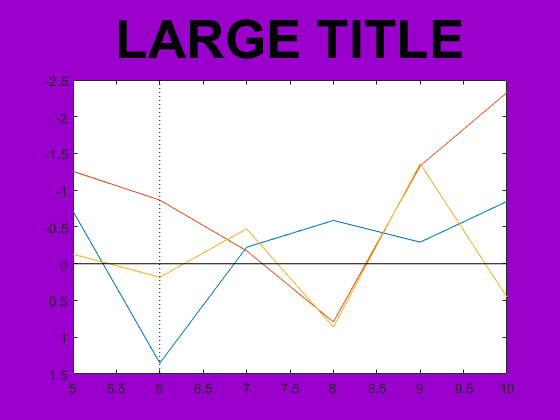

set(titleh,'FontSize',40)
set(titleh,'String','LARGE TITLE')

% Let's touch up the figure with some lines showing the 0 crossings. 
% We can do this without needing to know the exact axis limits:
hold on
plot(get(gca,'xlim'),[0 0],'k')
plot([6 6],get(gca,'ylim'),'k:')


% More generally, type "get(gca)" or "get(gcf)" to see what properties you
% can change and how to access them.

## subplots

% so far we've been putting all the data into one plot in the center of the
% figure. you can also use multiple plots:
figure
subplot(1,2,1) % 1 row, 2 columns, make the first subplot active
plot(randn(10,2))
subplot(1,2,2) % 1 row, 2 columns, make the second subplot active
plot(randn(10,2))

edgecolors='rgmk';

clf % clear figure
for subploti=1:4
    subplot(2,2,subploti)
    plot(1:subploti,(1:subploti)*2+1,'m-p','linewidth',3,'markerEdgeColor',edgecolors(subploti))
    set(gca,'xlim',[.5 4.5],'ylim',[1 10]) % fix X- and Y-axis ranges
    title([ 'Subplot ' num2str(subploti) repmat('!',1,subploti) ])
end

## basic image plotting

% You can also plot images in 2D. This is useful for 2D data such as
% time-frequency maps, connectivity matrices, etc.

figure
imagesc(randn(100,100))

% imagesc can also take x,y,z inputs, to make x- and y-axis values:
imagesc(1:10:100,0:.1:1,randn(100))

% now let's make this a bit smoother by convoling it with a 2D gaussian
xyrange = -1:.1:1;
[X,Y]   = meshgrid(xyrange); % this creates a grid of X and Y values
gaus2d  = exp(-(X.^2 + Y.^2));

% let's look at the Gaussian
imagesc(gaus2d)

imagesc(xyrange,xyrange,conv2(gaus2d,randn(100),'same'));

% you can toggle the colorbar, which shows you the mapping between color
% and value
colorbar

% you can also change the colormap (type "help graph3d" to see a list of
% default colormaps; you can also create your own)
colormap bone
colormap spring
colormap hot
colormap jet % this is the default
% hint for how to create your own: type "cmap=jet;" columns are RGB values


% there are other functions you can use for 2D data, including:
figure
data = conv2(gaus2d,randn(100),'same'); % 2D convolution

subplot(221) % that if you don't use variables and have fewer than 10 subplots, commas are not necessary
imagesc(xyrange,xyrange,data)
title('function: imagesc')

subplot(222)
surf(xyrange,xyrange,data)
shading interp
title('function: surf')

subplot(223)
contourf(xyrange,xyrange,data)
title('function: contourf')

subplot(224)
contourf(xyrange,xyrange,data,40,'linecolor','none')
title('function: contourf (with more parameters)')

colorbar
% note how imagesc flips the y-axis! (this can be changed: " set(gca,'YDir','normal') ")

% now let's change the color scaling
set(gca,'clim',[-1 1])
set(gca,'clim',[-10 2])
set(gca,'clim',[-10 20])


% There are many more ways to plot data and manipulate plots;
% this should get you started with the basics. 

% to save the figure, go File -> Save As...
%   you can save as .fig (readable in matlab only), pixelated formats like
%   .bmp or .png, or vector format like .eps (useful for importing into
%   Illustrator or Correl Draw)

## a bit more about images

% Images are just matrices of numbers. So are pictures. Load in the picture
% of amsterdam (note: Matlab must be in the directory in which the file lives).
amsterdam = imread('amsterdam.bmp');
whos amsterdam

  Name             Size                 Bytes  Class    Attributes

  amsterdam      734x700x3            1541400  uint8              



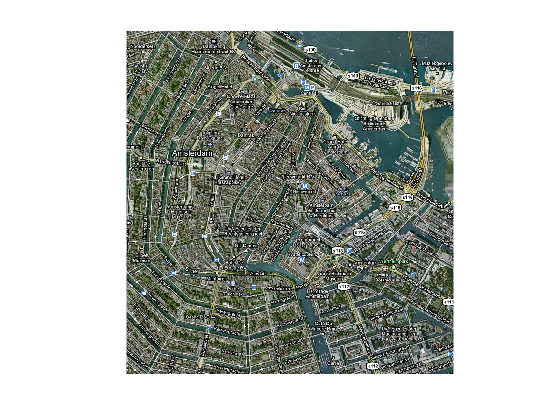


% note that this picture is a 2 (rows) x 2 (columns) x 3 (RGB) matrix
figure
imagesc(amsterdam)
axis image
axis off % or axis on
grid on  % only if axis is on
grid minor

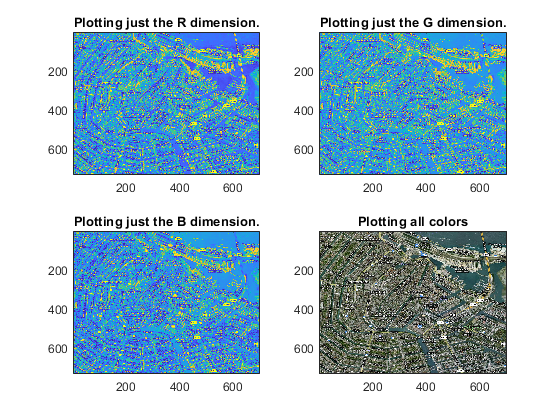


% try plotting the individual values separately:
title_color_components='RGB';
for subploti=1:4
    subplot(2,2,subploti)
    if subploti<4
        imagesc(amsterdam(:,:,subploti))
        title([ 'Plotting just the ' title_color_components(subploti) ' dimension.' ])
    else
        imagesc(amsterdam)
        title('Plotting all colors')
    end
end

## end.